## Задание 2. Линейные фильтры. Фильтр первого порядка

Рассмотрите такой же сигнал 


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


**Фильтр первого порядка**

$W_1 \left(p\right)=\frac{1}{\textrm{Tp}+1}$ - так выглядит наш фильтр

где $T>0$ - постоянная времени, $p$ - оператор дифференцирования, по просту - точечная производная

Берём функцию g, что... 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\textrm{else}
\end{array}\right.$$


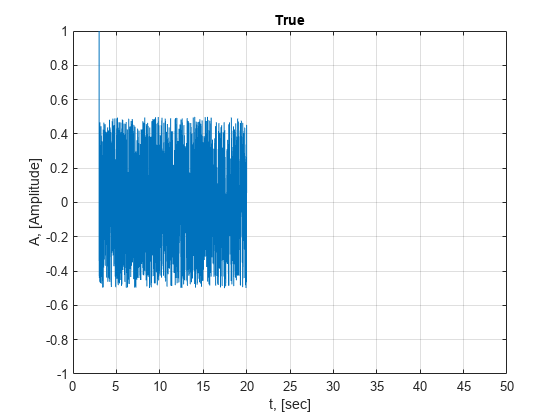

a = 3; b = 1; c = 0; d = 0;
t1 = -2; t2=3; 

dt  = 0.01;
t = -20:dt:20;

u = noisy(t, t1, t2, a, b, c, d);

figure( randi([1 3000],1,1) )
plot(t, u);
title("True")
grid on;
ylim([-1;1])
xlabel('t, [sec]');
xlim([0; 50])
ylabel('A, [Amplitude]');
hold off;

*Задаём параметры линейного фильтра*

V_min = -1500; V_max = 1500;
n = 4001;
freqs = linspace(V_min, V_max, n)

freqs = 1.0e+03 *

   -1.5000   -1.4992   -1.4985   -1.4977   -1.4970   -1.4963   -1.4955   -1.4948   -1.4940   -1.4932   -1.4925   -1.4917   -1.4910   -1.4903   -1.4895   -1.4888   -1.4880   -1.4872   -1.4865   -1.4857   -1.4850   -1.4843   -1.4835   -1.4828   -1.4820   -1.4812   -1.4805   -1.4797   -1.4790   -1.4783   -1.4775   -1.4768   -1.4760   -1.4752   -1.4745   -1.4737   -1.4730   -1.4723   -1.4715   -1.4708   -1.4700   -1.4692   -1.4685   -1.4678   -1.4670   -1.4663   -1.4655   -1.4647   -1.4640   -1.4632


#### Испытание 2

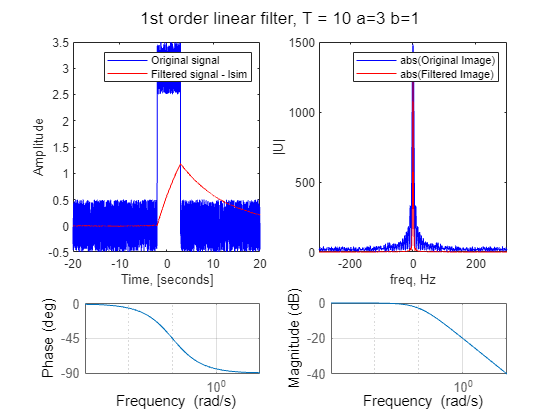

T = 10; % Постоянная времени
a = 3; b = 1; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

#### Испытание 3

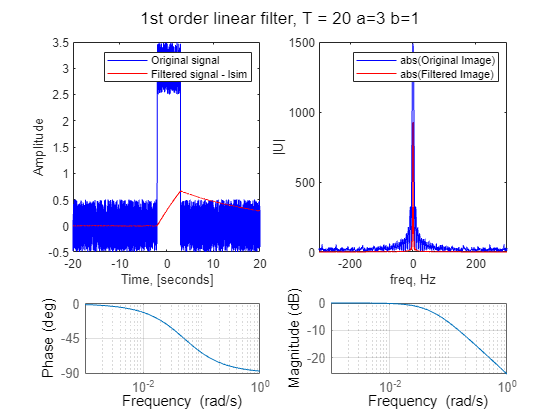

T = 20; % Постоянная времени
a = 3; b = 1; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

#### Испытание 4

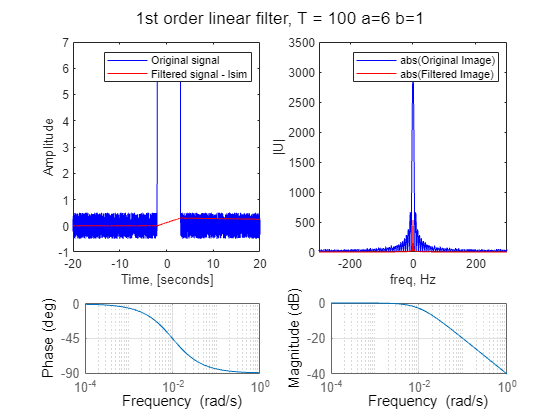

T = 100; % Постоянная времени
a = 6; b = 1; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

#### Испытание 5 - фильтрует лучше

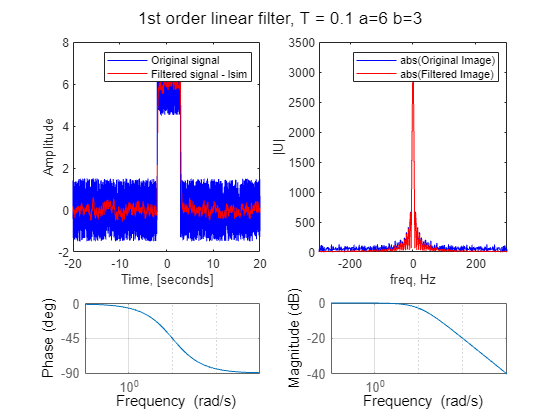

T = 0.1; % Постоянная времени
a = 6; b = 3; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

#### Испытание 5 - фильтрует лучше

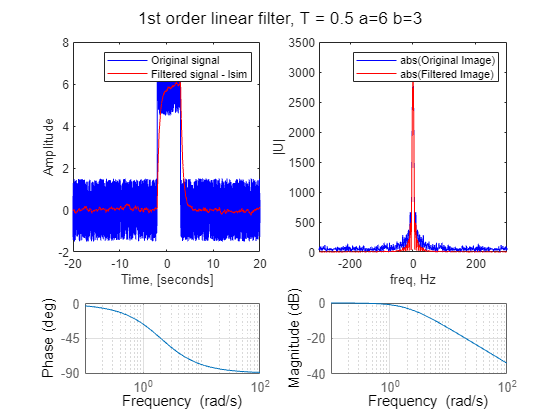

T = 0.5; % Постоянная времени
a = 6; b = 3; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

#### Испытание 6 - фильтрует лучше

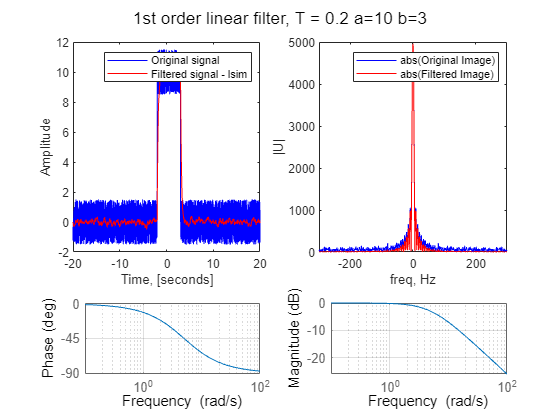

T = 0.2; % Постоянная времени
a = 10; b = 3; c = 0; d = 0;
t1 = -2; t2=3; 
u = noisy(t, t1, t2, a, b, c, d);
filter1_test(t, freqs,u, T, a, b)

### Специальный фильтр

% T1 = 7; T2 = 3; T3 = 5;
% b = [T1^2 2*T1 1];
% a = [T2*T3 T2+T3 1];
% W2=tf(b,a)
% bode(W2)

## Все функции, используемые в скрипте

**Вспомогательная функция "пошумим"**

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end


**Функция "пошумим"**

function y = noisy(t, t1, t2, a, b, c, d)
    y = g(t, a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
end

**Фильтр первого порядка - проведение одного испытания**

function filter1_test(t, freqs,u, T, a, b)
    % Создаем фильтр первого порядка (передаточную функцию Лапласа)
    p = tf('p');
    W1 = 1/(T*p + 1);
    
    y = lsim(W1,u,t);

    % Строим графики
    figure( randi([1 3000],1) )
    sgtitle("1st order linear filter, T = " + T + " a=" + a + " b=" + b)
    subplot(3, 2, [1,3])
    plot(t, u, 'b', t, y, 'r')
    xlabel('Time, [seconds]')
    ylabel('Amplitude')
    legend('Original signal', 'Filtered signal - lsim')
    
    subplot(3, 2, [2,4])
    plot(freqs, fftshift(abs(fft(u))), 'b', freqs, fftshift(abs(fft(y))), 'r')
    xlabel('freq, Hz')
    ylabel('|U|')
    xlim([-300,300])
    legend('abs(Original Image)', 'abs(Filtered Image)')
    % Вычисляем АЧХ и ФЧХ
    % Отделяем АЧХ от ФЧХ
    %[mag,phase,wout] = bode(W1);
   
    subplot(3,2,5);
    h1 = bodeplot(W1);
    setoptions(h1, 'MagVisible','off', 'Title', struct('String',''));
    grid on
    subplot(3,2,6);
    h2 = bodeplot(W1);
    setoptions(h2, 'PhaseVisible','off', 'Title', struct('String',''));
    grid on
    hold off;    
    save_file(T, a, b)
end


**Save file in the folder**

function save_file(T, a, b)
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
    T_str = strrep(sprintf('%0.2f', T), '.', '_');
    Name = "test_linear_filter=" + a+"_b="+b+ "_T="+ T_str;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');

end